clear clc
syms vin vout s c r w H denHreal denH numH positive

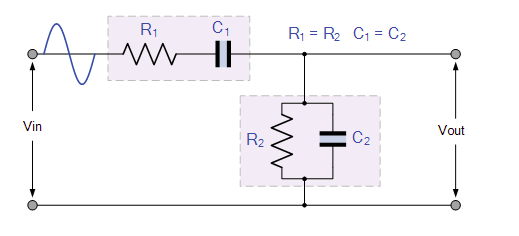

# Impedancia de entrada do bloco RC

Primeiro é feito a simplificação da assossiação paralelo

zinRC = paraleloSym(r, 1/(s*c))

$$zinRC = \frac{1}{c\,s+\frac{1}{r}}$$

Em seguida, soma-se o resultado com a associação serie R + C

zinRC = zinRC + r + 1/(s*c)

$$zinRC = r+\frac{1}{c\,s+\frac{1}{r}}+\frac{1}{c\,s}$$

zinRC = simplify(zinRC)

$$zinRC = r+\frac{1}{c\,s+\frac{1}{r}}+\frac{1}{c\,s}$$

# Impedancia de saida do bloco RC

Primeiro soma-se o elemento serie R+C

zoutRC = r + 1/(s*c)

$$zoutRC = r+\frac{1}{c\,s}$$

Em seguida  é feito o paralelo deste com o elemento paralelo R//C

zoutRC = paraleloSym(zoutRC, paraleloSym(r,1/(s*c)))

$$zoutRC = \frac{1}{\frac{1}{r+\frac{1}{c\,s}}+c\,s+\frac{1}{r}}$$

zoutRC = simplify(zoutRC)

$$zoutRC = \frac{r\,\left(c\,r\,s+1\right)}{c^{2}\,r^{2}\,s^{2}+3\,c\,r\,s+1}$$